# **Miniprojekt B**

**Mathias Vraa    ***au618687*

## **Formål**

Følgene tekst er taget fra øvelsesvejledningen:

*"Lav i Matlab et analysesystem, som baserer sig på Diskret Fourier Transformation (DFT). Systemet skal kunne lave DFT (vha. fft.m funktionen) på vilkårlige signaler og vise størrelsen af DFT’en med korrekte akser og skalering."*

*"Inkluder kortfattet teori, essentiel kode samt passende konklusioner."*

## **Implementation**

Hver opgave indeholder introduktion, implementation, resultater og diskussion. Resultater er vist under de grå kode blokke.

### **Opgave 1**

***"Find på nettet eksempler på disse to signaler: Vindmøllestøj (enten vingestøj eller generator/gear støj) og blæserstøj fra en computer. Der skal naturligvis haves kendskab til samplefrekvensen. Plot udvalgte 10 sekunder af begge signaler og beskriv ligheder og forskelle."***

Med audioread indlæses hvert lydsignal ind på et variabel (s1, s2). Samplefrekvens indlæses på fs. Længden er nøjagtigt 10 sekunder for hvert klip:

[s1, fs1] = audioread("lyd_opg1-4/windmill.wav"); % windmill
[s2, fs2] = audioread("lyd_opg1-4/pc_fan.wav"); % pc fan

De har begge samme sample frekvens. Jeg laver derfor ét variabel, fs, til dem begge:

fs1

fs1 = 44100

fs2

fs2 = 44100

fs = fs1

fs = 44100

Jeg finder tid pr. sample(Ts) ligesom i projekt A. Spilletiden (Tn) er præcis 10 sekunder for begge klip. Mængden af sample(n) er også ens for de to klip, da de har samme sample rate:

Ts = 1/fs % sekunder

Ts = 2.2676e-05

Tn = 10 % sekunder

Tn = 10

n = fs * Tn % antal sample

n = 441000

Tidaksen kan nu beregnes. Vi starter på 0, springer med Ts og stopper med at springe når Tn nåes:

t = 0:Ts:Tn-Ts;

Signalerne kan nu plottes.

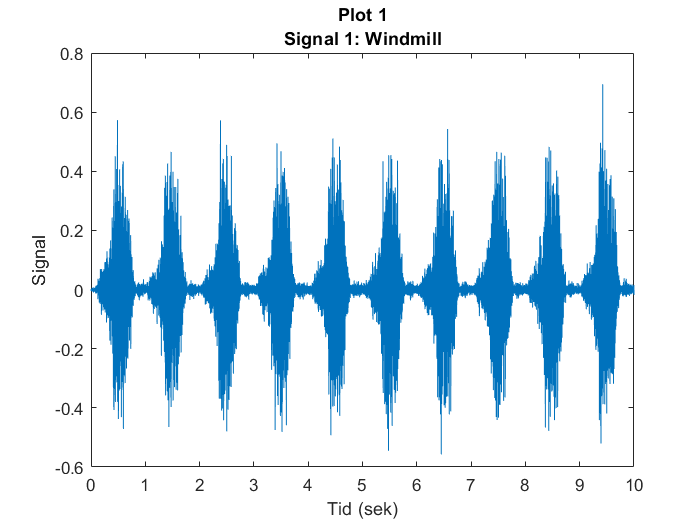

% windmill
plot(t,s1)
title("Plot 1" + newline + "Signal 1: Windmill");
ylabel("Signal");
xlabel("Tid (sek)");

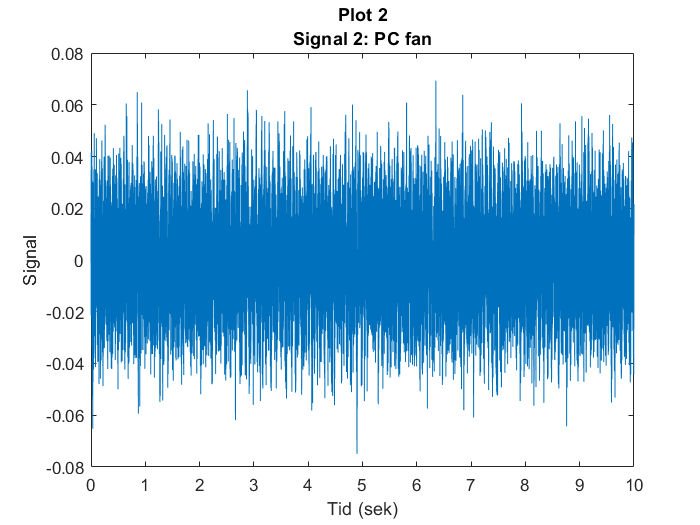


% pc fan
plot(t,s2)
title("Plot 2" + newline + "Signal 2: PC fan");
ylabel("Signal");
xlabel("Tid (sek)");

En vindmølle og en pc blæser er teknisk set to ens komponenter - vindmøllen er dog meget større. Vindmøllen bevæger sig langt langsommere end en blæser - den har altså en lavere frekvens. Det kan man se på plottet, da hver spike svarer til en vinge der suser forbi mikrofonen. Det samme gælder for en blæser, vingerne bevæger sig bare så hurtigt at lyden/plottet kommer til at virke konstant - den har altså en højere frekvens.

### **Opgave 2**

***"Lav frekvenstransformation på de 10 sekunders udsnit af signalerne i 1) og vis frekvensspektrene. Beskriv igen ligheder og forskelle."***

Jeg bruger funktionen fft til at finde "**f**ast **f**ourier **t**ransform" at mine signaler. Jeg får derfor en array med en række komplekse tal:

S1 = fft(s1);
S2 = fft(s2);

For at plotte signalerne tager jeg den absolutte værdi af det transformeret signal:

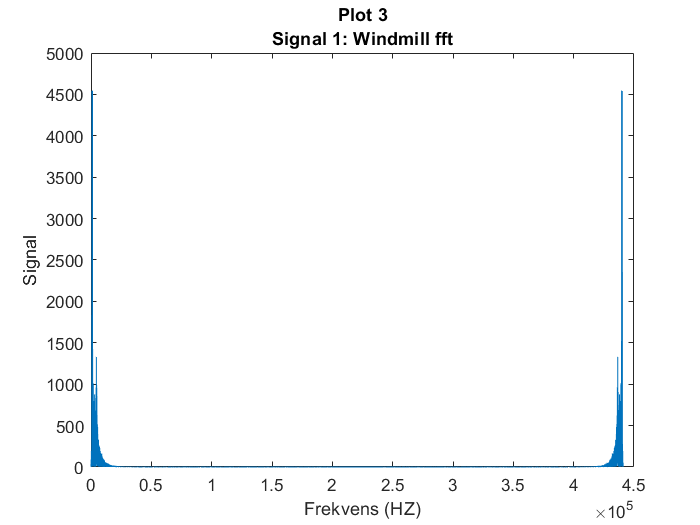

%windmill
plot(abs(S1))
title("Plot 3" + newline + "Signal 1: Windmill fft");
ylabel("Signal");
xlabel("Frekvens (HZ)");

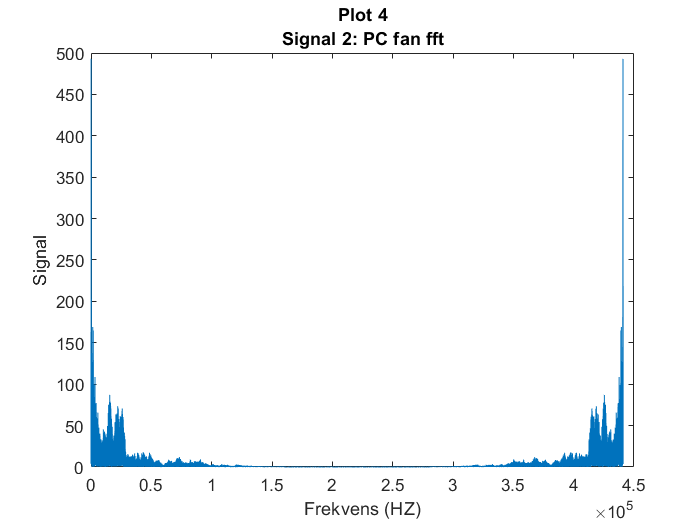


%pc fan
plot(abs(S2))
title("Plot 4" + newline + "Signal 2: PC fan fft");
ylabel("Signal");
xlabel("Frekvens (HZ)");

Fft deler signalet op efter frekvens. Frekvens ligger langs x-aksen og hyppighed for frekvens i siganlet er amplituden. For at kunne plotte bruges abs funktionen som finder den absolutte værdi. Plottet vil altid være spejlvendt - vi fokusere kun på det der ligger på den vestre side. 

Som nævnt i opgave 1 er frekvensen for en vindmøllen langsommere end pc blæseren. Den har derfor flere spike i den lave ende af spektret og meget få spikes i den høje ende. PC blæseren har en hurtig frekvens, og den har derfor en del spikes i den høje ende af frekvens spektret.

### **Opgave 3**

***"Bestem lavfrekvent effekt Plow (under 60Hz) og højfrekvent effekt Phigh (over 60) for de to støjsignaler i 1). Udregn for de to signaler effektforholdet Plow/Phigh og diskuter. I hvilket er der mest lavfrekvent energi?"***

For at udføre denne opgave skal de to signaler først deles op i to dele. Dem over 60Hz og dem under. Da fft har opdelt efter frekvens er dette meget nemt. Jeg tager bare de første 60 indexer for dem under, og de sidste indexer for dem over. Den spejlvendte del skal ikke med, så jeg dividere med 2:

S1_u60 = abs(S1(1:60));
S1_o60 = abs(S1(61:end/2));

S2_o60 = abs(S2(1:60));
S2_u60 = abs(S2(61:end/2));

Nu bestemmes effekten for hver:

S1_plow = (1/length(S1_u60)) * sum(S1_u60.^2)

S1_plow = 131.1752

S1_phigh = (1/length(S1_o60)) * sum(S1_o60.^2)

S1_phigh = 3.9107e+03


S2_plow = (1/length(S2_u60)) * sum(S2_u60.^2)

S2_plow = 96.7319

S2_phigh = (1/length(S2_o60)) * sum(S2_o60.^2)

S2_phigh = 3.3067e+03

Effekt forholdet beregnes:

S1_ratio = S1_plow/S1_phigh

S1_ratio = 0.0335

S2_ratio = S2_plow/S2_phigh

S2_ratio = 0.0293

### **Opgave 4**

***"Udregn frekvensopløsningen for de to signaler."***

Frekvensoplæsningen beregnes ved at dividere sample frekvensen med samples.

freq_res = fs/n % Hz

freq_res = 0.1000

Frekvens resolution er det spring vi tager langs x-aksen på et fft plot. Med andre ord, man tager sample frekvensen og opdeler den med mængden af samples.

### **Opgave 5**

***"Lav DFT på et telefon dial-up signal (otte cifre). Hvilke frekvenser (slå dem op) skal de enkelte cifre indeholde? Identificer disse på frekvensspektret."***

Jeg indlæser først mit dial up signal på et variabel. Det dial up signal jeg har valgt, indeholder sekvensen "**50736433**". Sample frekvensen(fs_dial) er 8000Hz:

[s_dial, fs_dial] = audioread("8_digit_dial.wav"); % 8 digit dial tone
fs_dial % Hz

fs_dial = 8000

Før jeg fourier transformere, laver jeg min frekvens akse. Til det, skal jeg bruge sample længden (n_dial) og frekvens resolution (fRes_dial):

n_dial = length(s_dial)

n_dial = 7580

fRes_dial = fs_dial / n_dial

fRes_dial = 1.0554

Jeg laver nu min frekvens akse. Den skal starte på 0, springe med intervallet svarene til frekvens resolution og stoppe når den når enden af samples (resolution gange sample mængde):

freqX = 0:fRes_dial:fRes_dial*(n_dial-1)

freqX = 	1.0e+03 *

         0    0.0011    0.0021    0.0032    0.0042    0.0053    0.0063    0.0074    0.0084    0.0095    0.0106    0.0116    0.0127    0.0137    0.0148    0.0158    0.0169    0.0179    0.0190    0.0201    0.0211    0.0222    0.0232    0.0243    0.0253    0.0264    0.0274    0.0285    0.0296    0.0306    0.0317    0.0327    0.0338    0.0348    0.0359    0.0369    0.0380    0.0391    0.0401    0.0412    0.0422    0.0433    0.0443    0.0454    0.0464    0.0475    0.0485    0.0496    0.0507    0.0517


Jeg laver DFT på signalet med fft funktionen og plotter langs frekvens aksen som jeg lige har lavet:

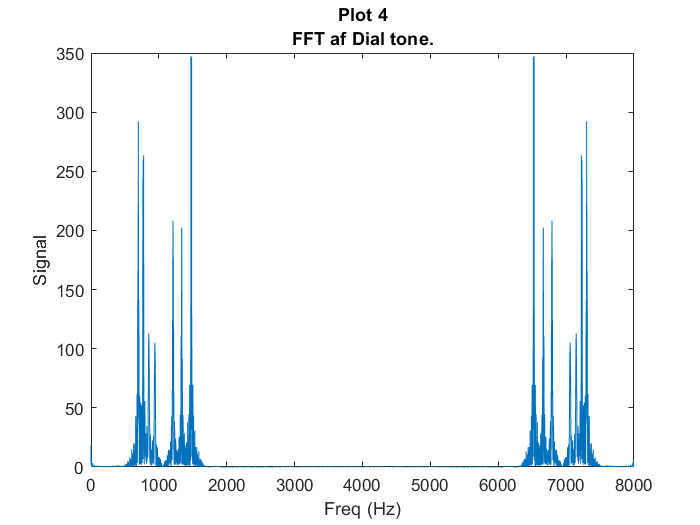

S_dial = fft(s_dial);

% dial tone plot
plot(freqX,abs(S_dial))
title("Plot 4" + newline + "FFT af Dial tone.");
ylabel("Signal");
xlabel("Freq (Hz)");

Frekvenser for hvert enkelt key er vist her. Som man kan se betår hvert key tryk af to sekvenser - dvs. 2 frekvenser overlapper og laver én tone:

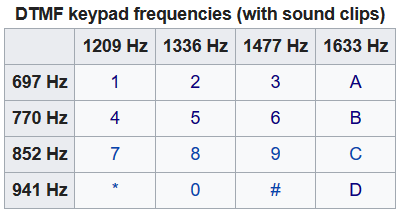

***Figur #:*** Table over keypad frekvenser fundet på Wikipedia.

Zoomes ind på højre side af plottet kan de forskellige frekvenser identificeres. Fft funktionen har delt frekvenserne op så de ligger langs x-aksen. Funktionen kan endda skille de overlappende toner fra hinanden. På figur # nedenunder kan man se hvor tonerne ligger - den røde tekst viser frekvensen for en spike og den grønne tekst viser den tilhørene key-tone.

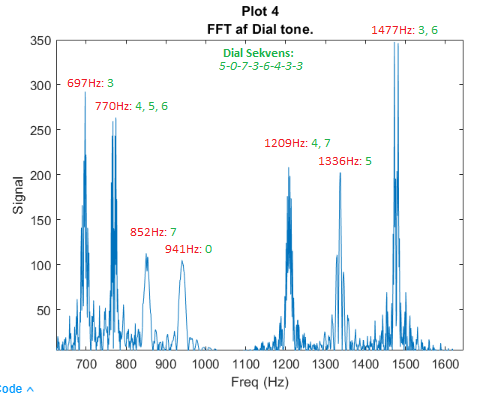

Som man kan se på figur # er nogle spikes større end andre. Det har noget at sige med hvor meget tonen er repræsenteret i signalet. 1477Hz er f.eks. repræsenteret i signalet ved 4 keytryk. Dens amplitude er derfor meget stor. 941Hz er kun repræsenteret med ét tryk (key 0), så den er derfor ca. 4 gange mindre. Her er en rangering af key presses pr. frekvens:

- **1477Hz:** 4 gange

- **697Hz:** 3 gange

- **770Hz:** 3 gange

- **1209Hz:** 2 gange

- **1336Hz:** 2 gange

- **852Hz:** 1 gang

- **941Hz:** 1 gang

### **Opgave 6**

***"Find følgende tre signaler: Vinglas der knipses på, en maskine der roterer, musik efter eget valg. Lav frekvenstransformation og vis amplitudespektrene – både med og uden udglatning. Diskuter de forskellige karakteristika i spektrene."***

Jeg indlæser valgte signaler: 

[s1, fs1] = audioread("lyd_opg6/vinglas.wav"); % vinglas der knipses på
[s2, fs2] = audioread("lyd_opg6/dc_motor.wav"); % roterende maskine
[s3, fs3] = audioread("lyd_opg6/yndigt_land.wav"); % musik: "Der er et yndigt land"

De har alle samme frekvens sample, så jeg laver en delt variabel, fs:

fs1

fs1 = 44100

fs2

fs2 = 44100

fs3

fs3 = 44100

fs = fs1;

n1 = length(s1)

n1 = 97137

n2 = length(s2)

n2 = 441000

n3 = length(s3)

n3 = 1896300


fRes1 = fs / n1

fRes1 = 0.4540

fRes2 = fs / n2

fRes2 = 0.1000

fRes3 = fs / n3

fRes3 = 0.0233


freqX1 = 0:fRes1:fRes1*(n1-1)

freqX1 = 	1.0e+04 *

         0    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0015    0.0016    0.0016    0.0017    0.0017    0.0018    0.0018    0.0019    0.0019    0.0020    0.0020    0.0020    0.0021    0.0021    0.0022    0.0022


freqX2 = 0:fRes2:fRes2*(n2-1)

freqX2 = 	1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


freqX3 = 0:fRes3:fRes3*(n3-1)

freqX3 = 	1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


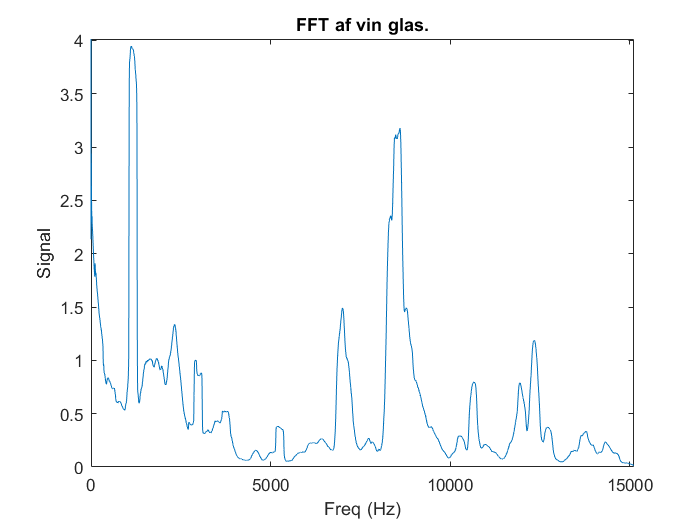


S1 = fft(s1);

% dial tone plot
plot(freqX1,smooth(abs(S1),500))
title("FFT af vin glas.");
ylabel("Signal");
xlabel("Freq (Hz)");

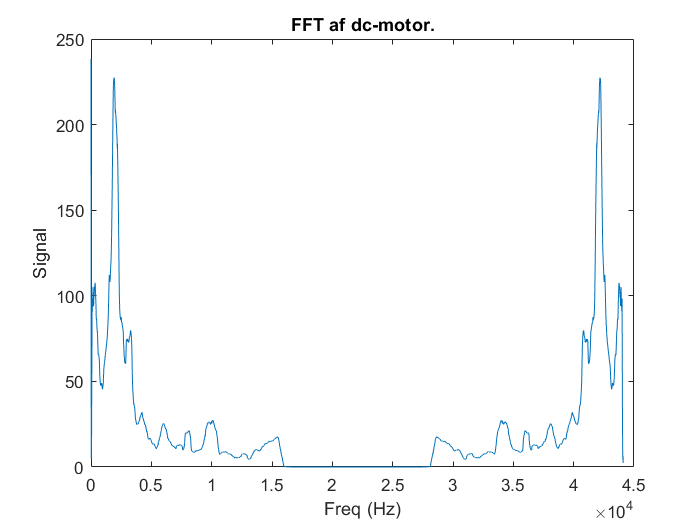


S2 = fft(s2);

% dial tone plot
plot(freqX2,smooth(abs(S2),5000))
title("FFT af dc-motor.");
ylabel("Signal");
xlabel("Freq (Hz)");

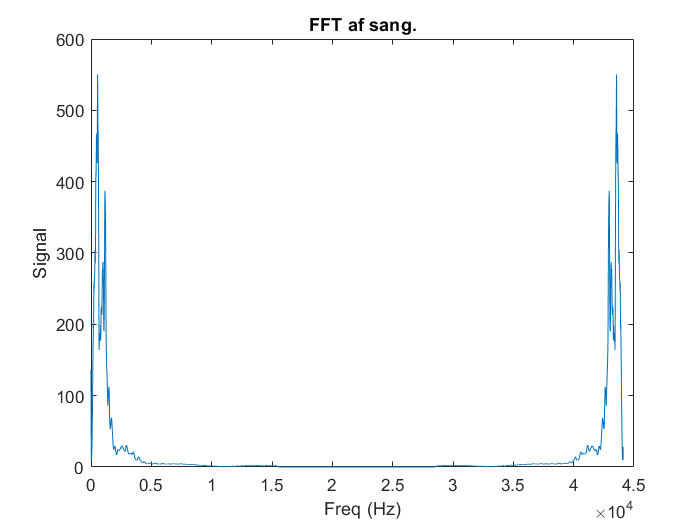


S3 = fft(s3);

% dial tone plot
plot(freqX3,smooth(abs(S3),5000))
title("FFT af sang.");
ylabel("Signal");
xlabel("Freq (Hz)");

### P3.15

Opgave 3.15 fra ***"Understanding Digital Signal Processing"*** af ***"Richard D. Lyons"***:

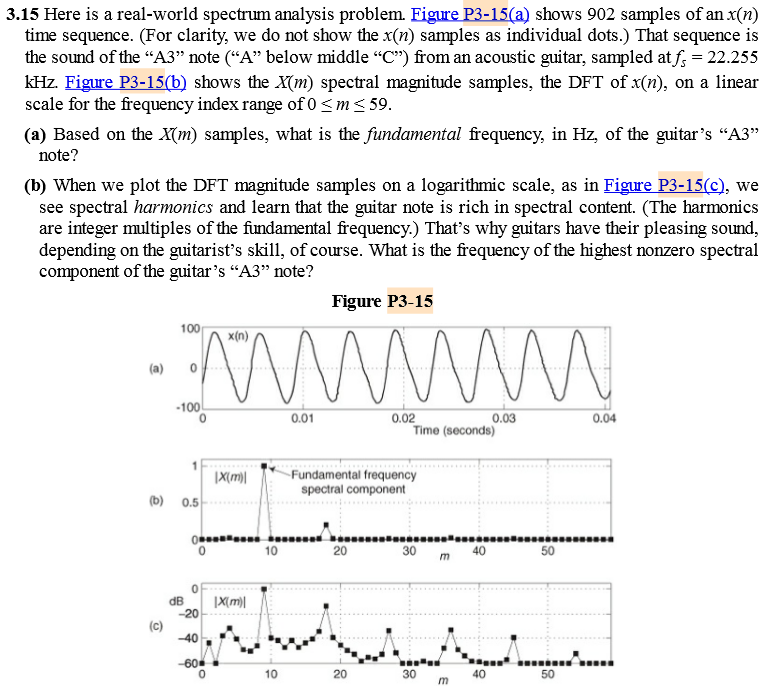

### P3.19

Opgave 3.19 fra ***"Understanding Digital Signal Processing"*** af ***"Richard D. Lyons"***:

## **Konklusion**